## Нахождение корня функции одной переменной.

1. Встроенная функция fzero

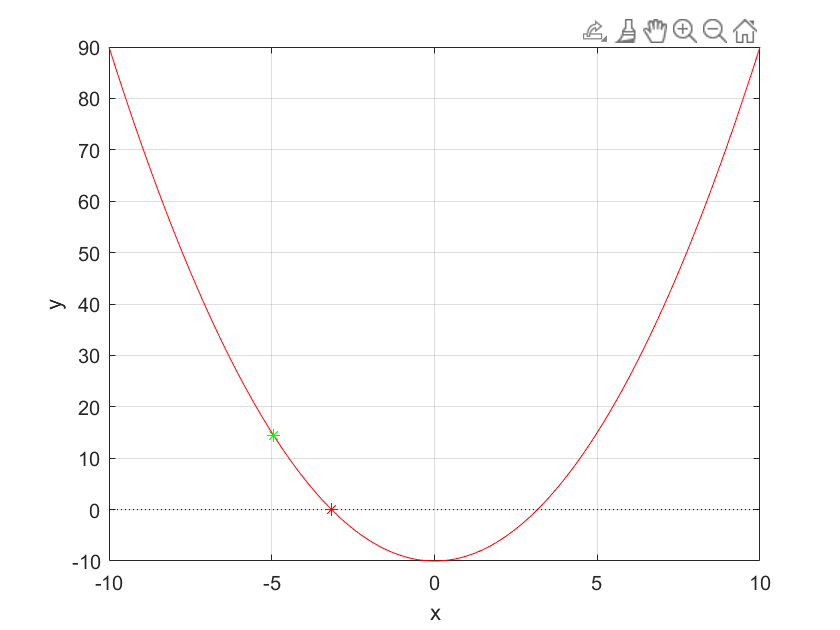

clear;
clc;
a = 10;
x = linspace(-10, 10, 1000);
Fun = @(x) x.*x - a;
plot(x, Fun(x), 'r' , x, x*0, ':k');
grid on;
xlabel("x");
ylabel("y");

[z, ~] = ginput(1);
[zr, fr] = fzero(Fun, z);
hold on;
plot(zr, fr, 'r*', z, Fun(z), 'g*');
hold off;

disp("The root equals " + zr);

The root equals -3.1623


2. Численные методы решения уравнений

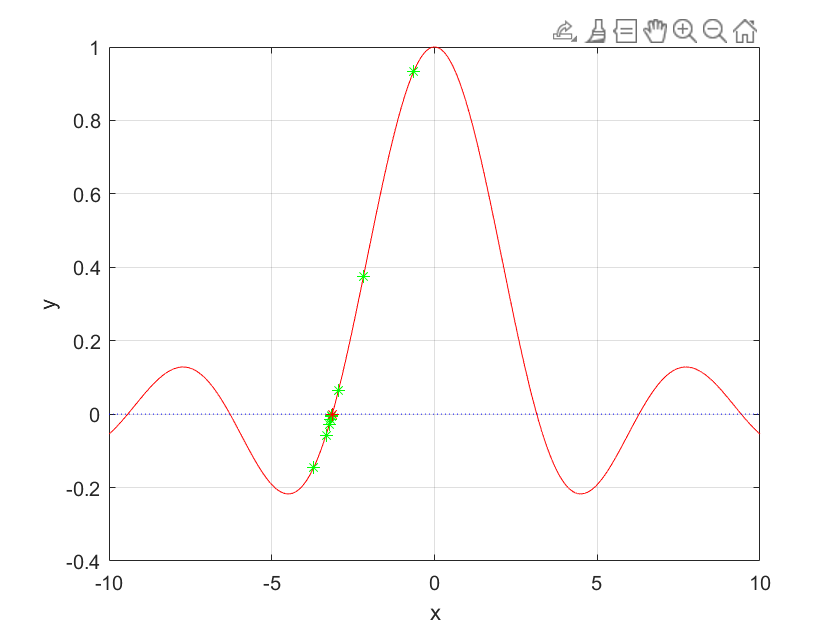

myFun1 = @(x) sin(x)./x;
myFun2 = @(x) 1 + (1 + sin(x) - cos(x)).^2 - (sin(2*x) - cos(2*x) - 0.2).^2;
myFun3 = @(x) sin(exp(x));
myFun4 = @(x) sin(x.*(1-x));
myFun5 = @(x) x.*sin(x) - cos(x);

eps = 0.000001;
x = linspace(-10, 10, 10000);
[root, iterations] = rootOfFunctionHalvedInterval(myFun1, x, eps);

disp("The number of iterations = " + iterations);

The number of iterations = 20


disp("The root equals " + root);

The root equals -3.1416


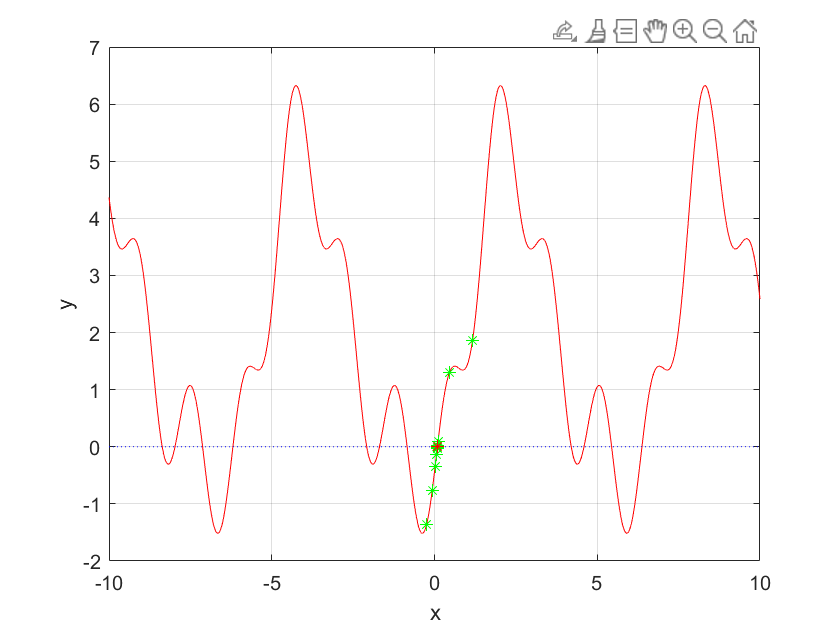


x = linspace(-10, 10, 10000);
[root, iterations] = rootOfFunctionHalvedInterval(myFun2, x, eps);

disp("The number of iterations = " + iterations);

The number of iterations = 23


disp("The root equals " + root);

The root equals 0.09017


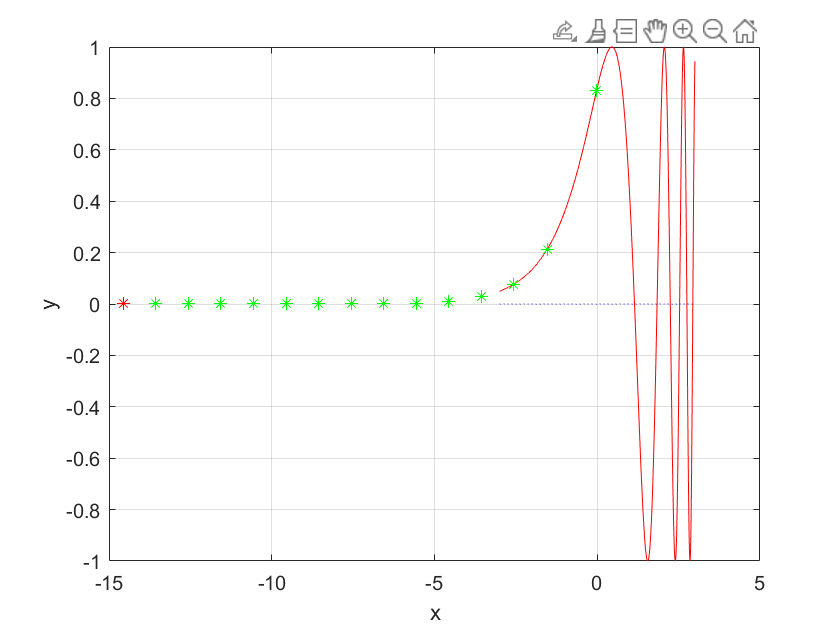



x = linspace(-3, 3, 10000);
[root, iterations] = rootOfFunctionNewton(myFun3, x, eps);

disp("The number of iterations = " + iterations);

The number of iterations = 14


disp("The root equals " + root);

The root equals -14.5607


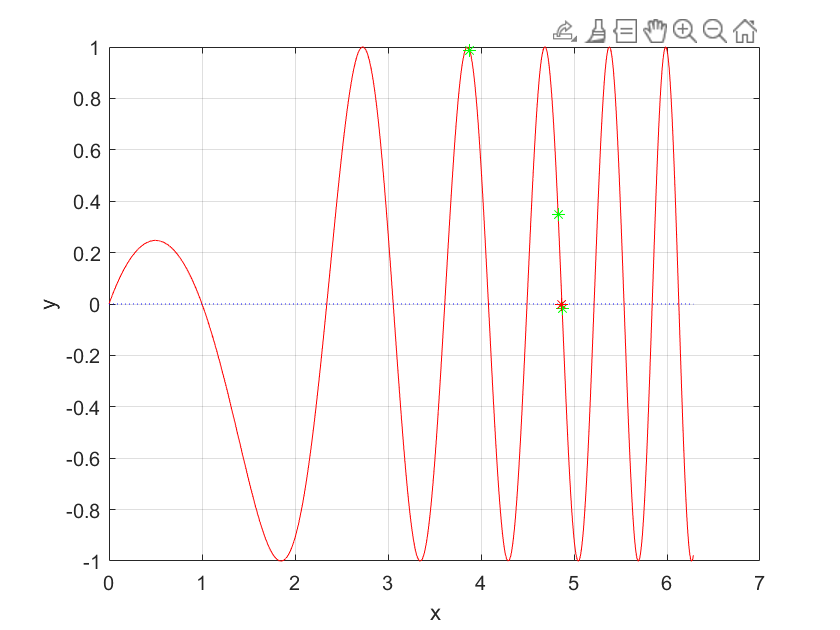


x = linspace(0, 2*pi, 10000);
[root, iterations] = rootOfFunctionNewton(myFun4, x, eps);

disp("The number of iterations = " + iterations);

The number of iterations = 4


disp("The root equals " + root);

The root equals 4.8703


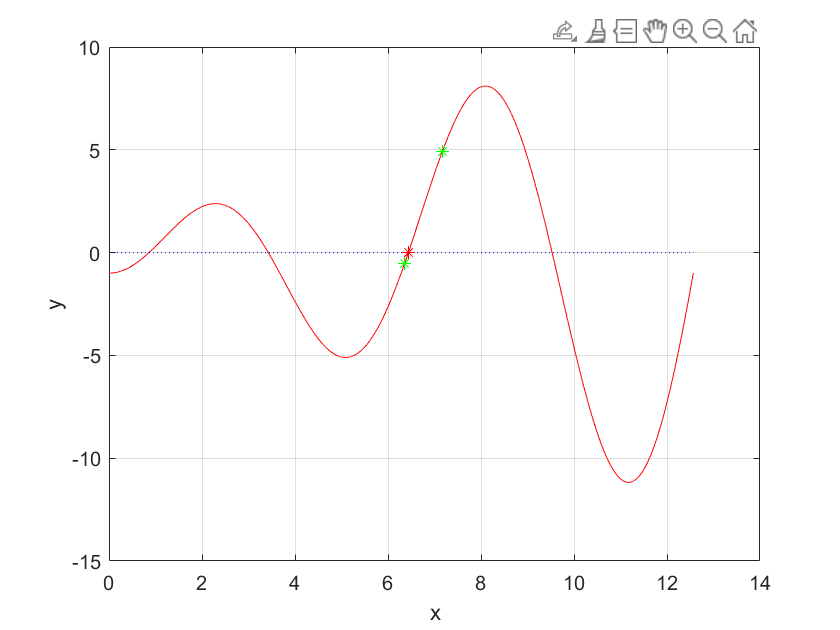


x = linspace(0, 4*pi, 10000);
[root, iterations] = rootOfFunctionNewton(myFun5, x, eps);

disp("The number of iterations = " + iterations);

The number of iterations = 4


disp("The root equals " + root);

The root equals 6.4373


2.1. Функция, ищущая корень методом деления отрезка пополам

function [out1, out2] = rootOfFunctionHalvedInterval(myFun, x, eps)
    plot(x, myFun(x), 'r' , x, x*0, ':b');
    grid on;
    xlabel("x");
    ylabel("y");
    [z1, ~] = ginput(1);
    [z2, ~] = ginput(1);
    
    while myFun(z1) * myFun(z2) > 0
        disp('You have chosen wrong points. Please try again.');
        [z1, ~] = ginput(1);
        [z2, ~] = ginput(1);
    end
    
    hold on;
    plot(z1, myFun(z1), 'g*');
    plot(z2, myFun(z2), 'g*');
    
    for i = 1:1000
        if myFun( (z1+z2)/2 ) * myFun(z1) > 0
            z1 = (z1+z2)/2;
        else
            z2 = (z1+z2)/2;
        end
    
        plot(z1, myFun(z1), 'g*');
        plot(z2, myFun(z2), 'g*');
    
        if abs(myFun(z1) - myFun(z2)) < eps
            break;
        end
    end
    plot(z1, myFun(z1), 'r*');
    hold off;
    out1 = z1;
    out2 = i;
end



2.2. Функция, ищущая корень методом Ньютона

function [out1, out2] = rootOfFunctionNewton(myFun, x, eps)
    h = 0.0000001;
    plot(x, myFun(x), 'r' , x, x*0, ':b');
    grid on;
    xlabel("x");
    ylabel("y");
    [x1, ~] = ginput(1);
    hold on;
    plot(x1, myFun(x1), 'g*');

    for iter = 1:1000
        x1 = x1 - h*myFun(x1)/(myFun(x1 + h) - myFun(x1));
        %plot(x, myFun(x1) + (myFun(x1 + h) - myFun(x1))*(x-x1)/h, '--k');
        plot(x1, myFun(x1), '*g');
        if abs(myFun(x1)) < eps
            break;
        end
    end
    plot(x1, myFun(x1), 'r*');
    hold off;
    out1 = x1;
    out2 = iter;
end